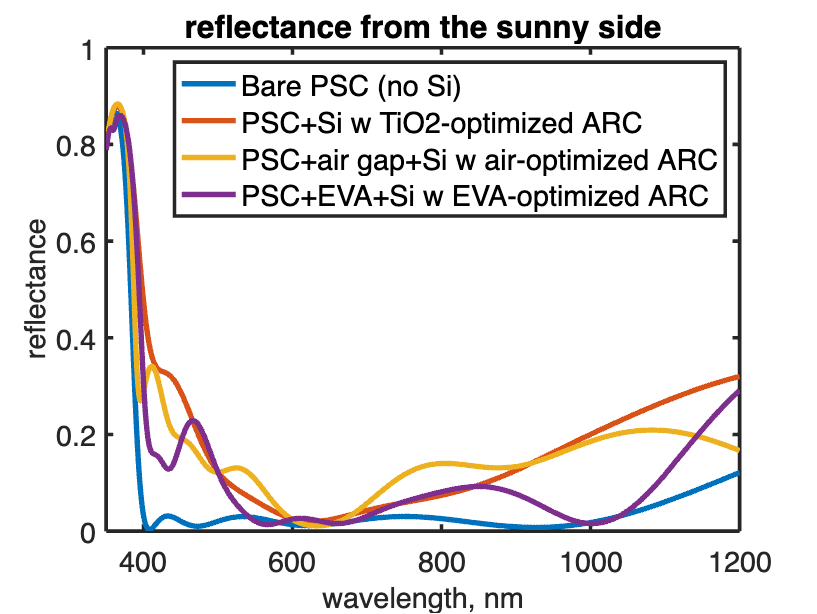

%% SCRIPT FOR TESTING LIGHT PROPAGATION THROUGH DIFFERENT PSCs
% -------------------------------------------------------------------------
%% GENERAL INPUT DATA
% -------------------------------------------------------------------------
lam = linspace(350, 1200, 851);
Bragg = repmat(["SiO2", "TiO2"],1,4); % materials of Bragg layers
matPSC = [Bragg,"gls",fliplr(Bragg)]; % PSC
dBragg =  [110.18, 25.18, 27.09, 50, 22.83, 33.65, 44.78, 12.68]; % thicknesses
dgls = 3e6; dPSC = [dBragg, dgls, fliplr(dBragg)]; % thicknesses
incoh = 9; % incoherent glass is 9th layer
theta = 0; % angle of incidence, normal
% -------------------------------------------------------------------------
%% CALCULATING SPECTRA
% -------------------------------------------------------------------------
% optimized Bragg, ATR measured in Fraunhofer
% sun -> air|(SiO2|TiO2)x4|glass|(TiO2|SiO2)x4|air
% -------------------------------------------------------------------------
materials = ["air",matPSC,"air"];
stack = set_stack( materials, dPSC, lam, theta, incoh );
[Aair, Tair, Rair] = ATR1D( stack );
% -------------------------------------------------------------------------
% optimized Bragg put on top of Si cell with ARC optimized to SiO2
% sun -> air|(SiO2|TiO2)x4|glass|(TiO2|SiO2)x4|SiO2-ARC|Si
% -------------------------------------------------------------------------
materials = ["air",matPSC,"const=2.5181","aSi"];
dARC = 59.6; d = [dPSC,dARC];
stack = set_stack( materials, d, lam, theta, incoh );
[~, ~, RTiO2Si] = ATR1D( stack );
% -------------------------------------------------------------------------
% optimized Bragg put on top of Si cell with ARC optimized to air
% sun -> air|(SiO2|TiO2)x4|glass|(TiO2|SiO2)x4|air|air-ARC|Si
% -------------------------------------------------------------------------
materials = ["air",matPSC,"air","const=2.0661","aSi"];
dair = 500; dARC = 72.6; d = [dPSC,dair,dARC];
stack = set_stack( materials, d, lam, theta, incoh );
[~, ~, RairSi] = ATR1D( stack );
% -------------------------------------------------------------------------
% optimized Bragg put on top of Si cell with ARC optimized to EVA
% sun -> air|(SiO2|TiO2)x4|glass|(TiO2|SiO2)x4|SiO2ARC|Si
% -------------------------------------------------------------------------
materials = ["air",matPSC,"EVA","const=2.5245","aSi"];
dEVA = 500; dARC = 59.4; d = [dPSC,dEVA,dARC];
stack = set_stack( materials, d, lam, theta, incoh );
[~, ~, REVASi] = ATR1D( stack );
% -------------------------------------------------------------------------
%% PLOTTING RESULTS
% -------------------------------------------------------------------------
figure();
plot(lam,Rair.sp,lam,RTiO2Si.sp,lam,RairSi.sp,lam,REVASi.sp,'LineWidth',3);
legend('Bare PSC (no Si)', ...
    'PSC+Si w TiO2-optimized ARC', ...
    'PSC+air gap+Si w air-optimized ARC', ...
    'PSC+EVA+Si w EVA-optimized ARC', ...
    'Location','northeast','FontSize',16);
xlim([lam(1) lam(end)]); ylim([0 1]);
xlabel('wavelength, nm','FontSize',16)
ylabel('reflectance','FontSize',16)
title('reflectance from the sunny side')

% -------------------------------------------------------------------------